# TD N°3 2020-21 deflection

We consider the following beam :

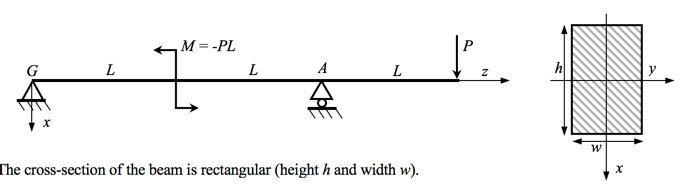

## 1) Shear and moment **diagram**

clear all
syms P L z RG RA C1 C2 C3 C4 C5 T1(z) T2(z)
% reactions
eq1=RG+RA+P;
eq2=-P*L+2*L*RA+3*L*P;
%s=solve([eq1,eq2],[RG,RA])
%RG=s.RG
%RA=s.RA

[A,B]=equationsToMatrix([eq1,eq2],[RG,RA]);
    mat=inv(A)*B;
RG=simplify(mat(1))

$$RG = 0$$

RA=simplify(mat(2))

$$RA = -P$$



%fundamental diagram
T1(z)=0;
T2(z)=0;
T3(z)=RA;
M1(z)=-int(T1,z)+C3;
M2(z)=-int(T1,z)+C4;
M3(z)=-int(T3,z)+C5;

eq1=M1(0)==0;
eq2=M1(L)-M2(L)-P*L==0;
eq3=M3(3*L)==0;
[A,B]=equationsToMatrix([eq1,eq2,eq3],[C3,C4,C5]);
    mat=inv(A)*B

$$mat = \left(\begin{array}{c} 0\\ -L\,P\\ -3\,L\,P \end{array}\right)$$

M1(z)=subs(M1(z),C3,mat(1))

$$M1(z) = 0$$

M2(z)=subs(M2(z),C4,mat(2))

$$M2(z) = -L\,P$$

M3(z)=subs(M3(z),C5,mat(3))    

$$M3(z) = P\,z-3\,L\,P$$

## (2) Deflexion curve

clear C1 C2 C3 C4 C5
syms C1 C2 C3 C4 C5 C6 E I
%Mfy1(z)=0 ; Mfy2(z)=-P*L; Mfy3(z)=P*z-3*L*P;

% integration Bresse equation
du_dz1(z)=-1/(E*I)*int(M1(z),z)+C1; 
du_dz2(z)=-1/(E*I)*int(M2(z),z)+C2;
du_dz3(z)=-1/(E*I)*int(M3(z),z)+C3;
u1(z)=int(du_dz1(z),z)+C4

$$u1(z) = C_{4}+C_{1}\,z$$

u2(z)=int(du_dz2(z),z)+C5

$$u2(z) = C_{5}+C_{2}\,z+\frac{L\,P\,z^{2}}{2\,\text{E}\,\text{I}}$$

u3(z)=int(du_dz3(z),z)+C6

%Boundary equations
    e1=u1(0)==0;       
    e2=u2(2*L)==0;
    e3=du_dz1(L)-du_dz2(L)==0;
    e4=du_dz2(2*L)-du_dz3(2*L)==0;
    e5=u1(L)==u2(L);
    e6=u2(2*L)-u3(2*L)==0;
    
[A,B]=equationsToMatrix([e1,e2,e3,e4,e5,e6], [C1,C2,C3,C4,C5,C6])

$$A = \left(\begin{array}{cccccc} 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 2\,L & 0 & 0 & 1 & 0\\ 1 & -1 & 0 & 0 & 0 & 0\\ 0 & 1 & -1 & 0 & 0 & 0\\ L & -L & 0 & 1 & -1 & 0\\ 0 & 2\,L & -2\,L & 0 & 1 & -1 \end{array}\right)$$

$$B = \left(\begin{array}{c} 0\\ -\frac{2\,L^{3}\,P}{\text{E}\,\text{I}}\\ \frac{L^{2}\,P}{\text{E}\,\text{I}}\\ \frac{2\,L^{2}\,P}{\text{E}\,\text{I}}\\ \frac{L^{3}\,P}{2\,\text{E}\,\text{I}}\\ \frac{8\,L^{3}\,P}{3\,\text{E}\,\text{I}} \end{array}\right)$$

mat=inv(A)*B              % Constant matrices

$$mat = \left(\begin{array}{c} -\frac{L^{2}\,P}{4\,\text{E}\,\text{I}}\\ -\frac{5\,L^{2}\,P}{4\,\text{E}\,\text{I}}\\ -\frac{13\,L^{2}\,P}{4\,\text{E}\,\text{I}}\\ 0\\ \frac{L^{3}\,P}{2\,\text{E}\,\text{I}}\\ \frac{11\,L^{3}\,P}{6\,\text{E}\,\text{I}} \end{array}\right)$$


u1(z)=subs(u1(z),C1,mat(1)); u1(z)=subs(u1(z),C4,mat(4))  % replace constants

$$u1(z) = -\frac{L^{2}\,P\,z}{4\,\text{E}\,\text{I}}$$

u2(z)=subs(u2(z),C2,mat(2)); u2(z)=subs(u2(z),C5,mat(5))

$$u2(z) = \frac{L^{3}\,P}{2\,\text{E}\,\text{I}}+\frac{L\,P\,z^{2}}{2\,\text{E}\,\text{I}}-\frac{5\,L^{2}\,P\,z}{4\,\text{E}\,\text{I}}$$

u3(z)=subs(u3(z),C3,mat(3)); u3(z)=subs(u3(z),C6,mat(6))

$$u3(z) = \frac{11\,L^{3}\,P}{6\,\text{E}\,\text{I}}-\frac{z\,\left(P\,z^{2}-9\,L\,P\,z\right)}{6\,\text{E}\,\text{I}}-\frac{13\,L^{2}\,P\,z}{4\,\text{E}\,\text{I}}$$

du_dz1(z)=subs(du_dz1(z),C1,mat(1))

$$du\_dz1(z) = -\frac{L^{2}\,P}{4\,\text{E}\,\text{I}}$$

du_dz2(z)=subs(du_dz2(z),C2,mat(2))

$$du\_dz2(z) = \frac{L\,P\,z}{\text{E}\,\text{I}}-\frac{5\,L^{2}\,P}{4\,\text{E}\,\text{I}}$$

du_dz3(z)=subs(du_dz3(z),C3,mat(3))

$$du\_dz3(z) = \frac{P\,z\,\left(6\,L-z\right)}{2\,\text{E}\,\text{I}}-\frac{13\,L^{2}\,P}{4\,\text{E}\,\text{I}}$$


u_max=u3(3*L)

$$u\_max = \frac{13\,L^{3}\,P}{12\,\text{E}\,\text{I}}$$

z_max=solve(du_dz2==0,z)

$$z\_max = \frac{5\,L}{4}$$

u_max_int=u2(solve(du_dz2==0,z))

$$u\_max\_int = -\frac{9\,L^{3}\,P}{32\,\text{E}\,\text{I}}$$

## **(3) plot of the fundamental diagram**

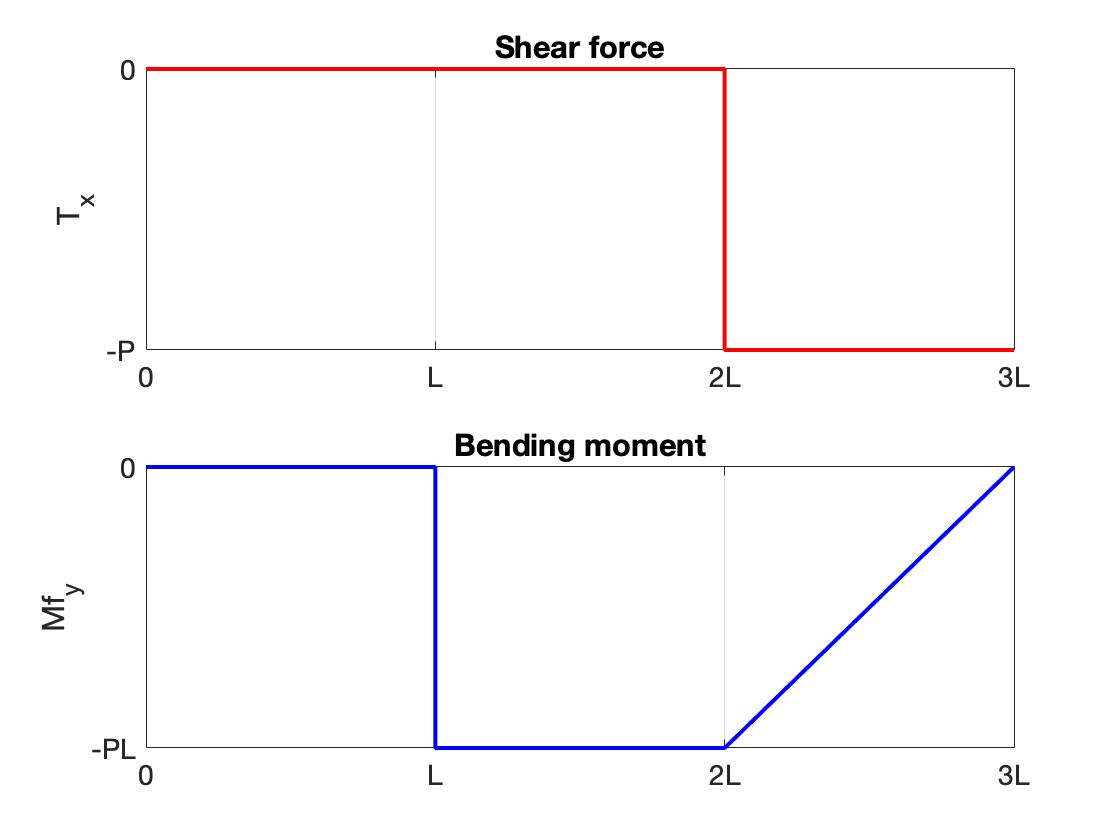

L=1; a=0.5; P=1000;
z1=0:L/10:L; z2=L:L/10:2*L; z3=2*L:L/10:3*L; z=[z1 z2 z3];
Tx1=eval(T1+(z1*0)); Tx2=eval(T2+(z2*0)); Tx3=eval(T3+(z3*0));
Tx=[Tx1 Tx2 Tx3];
Mf1=eval(M1(z1));
Mf2=eval(M2(z2)); Mf3=eval(M3(z3)); Mf=[Mf1 Mf2 Mf3];

figure
ax1 = subplot(2,1,1);  % plot of shear force
plot(ax1,z,Tx,'r','lineWidth',2)
title('Shear force')
ylabel('T_x','FontSize',14);
xticks([0  L 2*L 3*L]); xticklabels({'0','L','2L','3L'});
yticks([-P  0]); yticklabels({'-P','0'});
grid on
sca1 = gca; sca1.FontSize = 14;

ax2=subplot(2,1,2);   % plot of bending moment
plot(ax2,z,Mf,'b','lineWidth',2)
title('Bending moment')
xticks([0  L 2*L 3*L]); xticklabels({'0','L','2L','3L'});
ylabel('Mf_y','FontSize',14);
yticks([-P  0]); yticklabels({'-PL','0'});
grid on
sca2 = gca; sca2.FontSize = 14;

## 4) plot of the deflexion curve

P=1e3; E=220e9; L=1; w=40e-3; h=60e-3 ; I=w*h^3/12;   % plot of the curve : numerical values
z1=0:L/20:L; z2=L:L/20:2*L; z3=2*L:L/20:3*L; z=[z1 z2 z3];   % z- axis
u1=eval(u1(z1)) 

u1 =          0   -0.0001   -0.0002   -0.0002   -0.0003   -0.0004   -0.0005   -0.0006   -0.0006   -0.0007   -0.0008   -0.0009   -0.0009   -0.0010   -0.0011   -0.0012   -0.0013   -0.0013   -0.0014   -0.0015   -0.0016


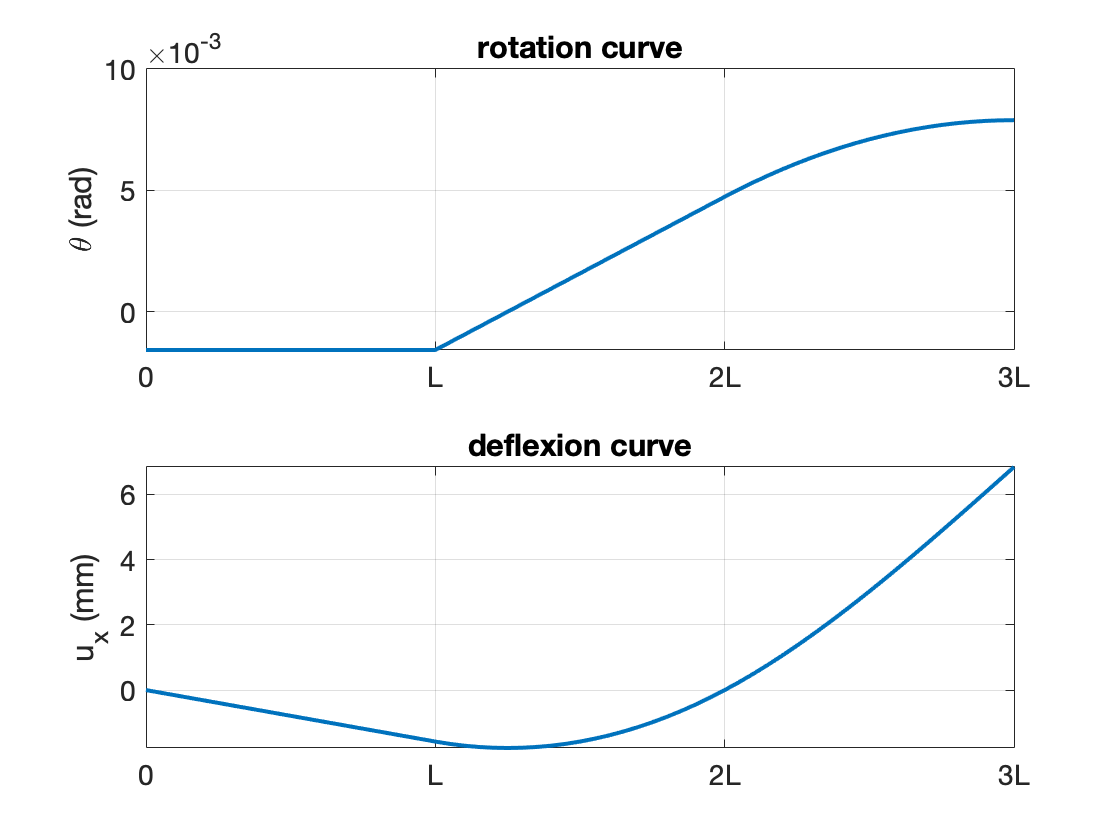

u2=eval(u2(z2)); u3=eval(u3(z3)); u=[u1 u2 u3];     % displacement
du_dz1=eval(du_dz1(z1)); du_dz2=eval(du_dz2(z2)); 
du_dz3=eval(du_dz3(z3)); du_dz=[du_dz1 du_dz2 du_dz3]; %rotation

figure
ax1 = subplot(2,1,1);   % plot of the rotation
    plot(ax1,z,du_dz,'lineWidth',2)
    title('rotation curve')
    ylabel('\theta (rad)','FontSize',14);
    xticks([0  L 2*L 3*L]); xticklabels({'0','L','2L','3L'})
    grid on
    sca1 = gca; sca1.FontSize = 14;
ax2=subplot(2,1,2);     % plot of the displacement curve
    plot(ax2,z,u*1e3,'lineWidth',2)
    title('deflexion curve')
    ylabel('u_x (mm)','FontSize',14);
    xticks([0  L 2*L 3*L]); xticklabels({'0','L','2L','3L'})
    grid on
    sca1 = gca; sca1.FontSize = 14;


u_max=13/12*L^3*P/E/I; fprintf("u_max = %1.2f mm",u_max*10e3)

u_max = 68.39 mm

## 4) maximum displacement

The maximum displacement is in $z=3L$ the value has been calculated in the block 2) and is therefore : $u_{max}=\frac{13L^3P}{12EI_y}$

The numerical value is : $u_{max}=6.8\, \mathrm{mm}$.

We could also calculate the maximum displacement on the negative side, since it is a maximum value, it is located at the point where $\frac{du}{dz}=0$, so in $z=\frac{5L}{4}$ which gives the value $u=-\frac{9L^3P}{32EI_y}$

## 5) Stress tensor


$$\bar\bar\sigma=\left[\begin{array}{ccc}0 & 0 &\sigma_{xz} \\0 & 0 & 0 \\\sigma_{xz} & 0 & \sigma_{zz}\end{array}\right]$$


with $\sigma_{zz}(x,z)=\frac{Mf_y(z)}{I_y}x$  and considering the simplified averaged value  $\sigma_{xz}(z)=-\frac{T_x}{S}$

clear all
syms P L z x w h E
assume(L>0)
I=w*h^3/12;
S=w*h;
T(z) = piecewise(0<=z<2*L, 0, 2*L<=z<=3*L,-P);
Mf(z)=piecewise(0<=z<L,0,L<=z<2*L,-P*L,2*L<=z<=3*L,P*z-3*P*L);
s_xz(z)=-T(z)/S;
s_zz(x,z)=Mf(z)/I*x;
s_zz(h/2,2*L)

$$ans = -\frac{6\,L\,P}{h^{2}\,w}$$

s_zz(h/2,3*L)

$$ans = 0$$